# Dijkstra's Algorithm on a grid

The skeleton code provided below contains the following 2D arrays:

`map` : An array of integer values which indicates the current status of each cell in the grid. 

    Different integer values are used to indicate the different possible states listed below:

        • Whether the node is part of an obstacle 

        • If the node is in freespace, 

        • Whether or not it has been visited 

        • Is currently on the list of nodes being considered.

`distanceFromStart`** : **This array encodes the current estimate for the distance between each node and the start node.

`parent`** : ** For every cell in the map this array records the index of its parent with respect to the algorithm, that is the next node along the shortest path to the start node.

On every iteration through the main loop the code finds the unvisited cell with the smallest distance value, i.e, the node that is the closest to the start node. 

The part of this function should consider the four neighbors of the cell -  the north, south east and west, and for each neighbor your function should decide if it needs to update the corresponding entries in the `distanceFromStart`, `map` and `parent` arrays. 

If you know how to use sub functions in Matlab you may find it useful to create one that you can then apply repeatedly to each of the neighboring cells, but this is not required.

 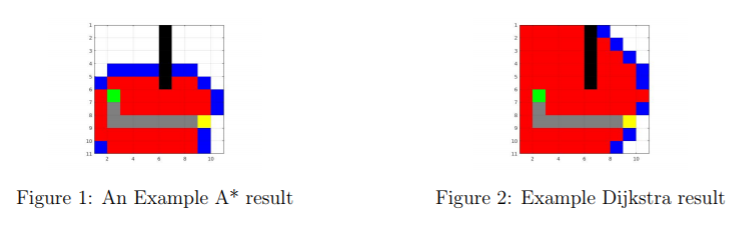 

 When you complete the code and run the associated test script it should show you an animation (Fig.1, Fig.2) of the algorithms progress. On these plots: 

    • The `yellow cell` is the goal and the `green cell` is the start location.

    • The `greyed out region` in the grid represents the path found by the planner. 

    • The `red cells` in the grid are all the nodes that have been visited by the planner and marked as expanded 

    • The` blue cells` are nodes that are currently on the list of cells that are being considered for expansion.

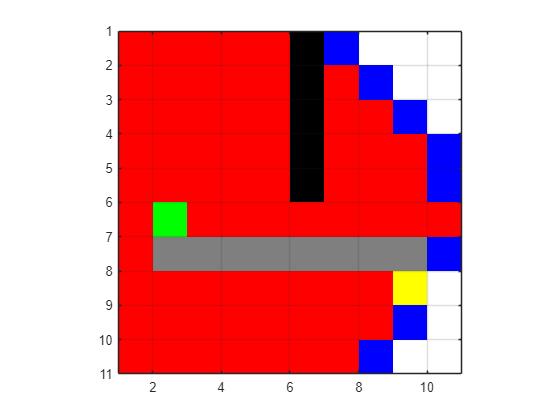

map = false(10); % Input Map Parameters
map (1:5, 6) = true; % Obstacle Declaration
start_coords = [6, 2]; % Starting Coordinates
dest_coords  = [8, 9]; % Destination Coordinates
drawMapEveryTime = true; % Display Outputs
[route, numExpanded] = DijkstraGrid(map, start_coords, dest_coords, drawMapEveryTime); % Implementation

function [route,numExpanded] = DijkstraGrid (input_map, start_coords, dest_coords, drawMapEveryTime)
    % Run Dijkstra's algorithm on a grid.
    % Inputs : 
    %   input_map : a logical array where the freespace cells are false or 0 and
    %   the obstacles are true or 1
    %   start_coords and dest_coords : Coordinates of the start and end cell
    %   respectively, the first entry is the row and the second the column.
    % Output :
    %    route : An array containing the linear indices of the cells along the
    %    shortest route from start to dest or an empty array if there is no
    %    route. This is a single dimensional vector
    %    numExpanded: Remember to also return the total number of nodes
    %    expanded during your search. Do not count the goal node as an expanded node.
    
    
    % set up color map for display
    % 1 - white - clear cell
    % 2 - black - obstacle
    % 3 - red = visited
    % 4 - blue  - on list
    % 5 - green - start
    % 6 - yellow - destination
    
    cmap = [1 1 1; ...
            0 0 0; ...
            1 0 0; ...
            0 0 1; ...
            0 1 0; ...
            1 1 0; ...
	        0.5 0.5 0.5];
    
    colormap(cmap);
    
    % variable to control if the map is being visualized on every
    % iteration
    % drawMapEveryTime = true;
    
    [nrows, ncols] = size(input_map);
    
    % map - a table that keeps track of the state of each grid cell
    map = zeros(nrows, ncols);
    
    map(~input_map) = 1; % Mark free cells
    map(input_map)  = 2; % Mark obstacle cells
    
    % Generate linear indices of start and dest nodes
    start_node = sub2ind(size(map), start_coords(1), start_coords(2));
    dest_node  = sub2ind(size(map), dest_coords(1),  dest_coords(2));
    
    map(start_node) = 5;
    map(dest_node)  = 6;
    
    % Initialize distance array
    distanceFromStart = Inf(nrows, ncols);
    
    % For each grid cell this array holds the index of its parent
    parent = zeros(nrows,ncols);
    
    distanceFromStart(start_node) = 0;
    
    % keep track of number of nodes expanded 
    numExpanded = 0;
    
    % Main Loop
    while true
        % Draw current map
        map(start_node) = 5;
        map(dest_node) = 6;
        
        % make drawMapEveryTime = true if you want to see how the 
        % nodes are expanded on the grid. 
        if (drawMapEveryTime)
            image(1.5, 1.5, map);
            grid on;
            axis image;
            drawnow;
        end
        
        % Find the node with the minimum distance
        [min_dist, current] = min(distanceFromStart(:));
        
        if ((current == dest_node) || isinf(min_dist))
            break;
        end;
        
        % Update map
        map(current) = 3;         % mark current node as visited
        distanceFromStart(current) = Inf; % remove this node from further consideration
        
        % Compute row, column coordinates of current node
        [i, j] = ind2sub(size(distanceFromStart), current);
        
        % ********************************************************************* 
        % YOUR CODE BETWEEN THESE LINES OF STARS
        
        % Visit each neighbor of the current node and update the map, distances
        % and parent tables appropriately.
        
        numExpanded = numExpanded + 1;
        % disp([i j]);

        for n = (j-1):2:(j+1)
            if (n>=1) && (n<=ncols)
                neighboors = sub2ind(size(map), i, n);
               if (map(neighboors) == 1)|| (map(neighboors) == 6)
                   map(neighboors) = 4;
                   distanceFromStart(neighboors) = min_dist + 1;
                   parent(neighboors) = current;
               end
            end
        end
    
        for k = (i-1):2:(i+1)
            if (k>=1) && (k<=nrows)
                neighboors = sub2ind(size(map), k, j);
               if (map(neighboors) == 1) || (map(neighboors) == 6)
                   map(neighboors) = 4;
                   distanceFromStart(neighboors) = min_dist + 1;
                   parent(neighboors) = current;
               end
            end
        end    
    end
        %*********************************************************************

    %% Construct route from start to dest by following the parent links
    if (isinf(distanceFromStart(dest_node)))
        route = [];
    else
        route = [dest_node];
        
        while (parent(route(1)) ~= 0)
            route = [parent(route(1)), route];
        end
        
        % Snippet of code used to visualize the map and the path
        for k = 2:length(route) - 1        
            map(route(k)) = 7;
            pause(0.1);
            image(1.5, 1.5, map);
            grid on;
            axis image;
        end
    end
end